% Чему равно наибольшее число, для которого можно вычислить факториал в пакете MATLAB?
x = 1;
i = 1;
while ~isinf(x)
    x = x*i;
    i = i + 1;
end
fprintf('%d – max number\n ', i-2);

170 – max number
 


factorial(170)

ans = 7.2574e+306

factorial(171)

ans = Inf

% Организуйте цикл, в котором вводите с клавиатуры название дня недели,
% и при помощи оператора switch определите номер дня недели по названию дня недели. 
% Выход из цикла – по вводу текстовой строки «exit».
% Обработайте некорректный ввод названия дня недели.

flag = 1;
while flag
day = input('Введите день недели: ', 's');
    switch upper(day)
    case{'ПОНЕДЕЛЬНИК'}
        disp('1-й день недели')
    case{'ВТОРНИК'}
        disp('2-й день недели')
    case{'СРЕДА'}
        disp('3-й день недели')
    case{'ЧЕРТВЕРГ'}
        disp('4-й день недели')
    case{'ПЯТНИЦА'}
        disp('5-й недели')
    case{'СУББОТА'}
        disp('6-й день недели')
    case{'ВОСКРЕСЕНЬЕ'}
        disp('7-й день недели')
    case{'EXIT'} 
        disp('Конец цикла')
        flag = 0;
    otherwise
        disp('Нет такого дня недели')
    end
end

Нет такого дня недели


3-й день недели


Конец цикла


% Организуйте цикл, в котором вводите с клавиатуры номер месяца, 
% и при помощи оператора switch определите название месяца по его номеру. 
% Обработайте некорректный ввод номера дня недели.
% Выход изцикла – по вводу числа 0.

flag = 1;
while flag
day = input('Введите номер месяца: ');
switch day
    case 1
        disp('Январь')
    case 2
        disp('Февраль')
    case 3
        disp('Март')
    case 4
        disp('Апрель')
    case 5
        disp('Май')
    case 6
        disp('Июнь')
    case 7
        disp('Июль')
    case 8
        disp('Август')
    case 9
        disp('Сентябрь')
    case 10
        disp('Октябрь')
    case 11
        disp('Ноябрь')
    case 12
        disp('Декабрь')
    case 0
        disp('Конец цикла')
        flag = 0;
    otherwise
        disp('Нет такого месяца')
end
end

Конец цикла


M=input('Input (nx2)-Matrix: ')

M =      1     2


% [1 2;4 1;5 1]

A=input('Input the Number : A = ');
disp(['The Number A is: ', int2str(A)])

The Number A is: 3


S=input('Input the String : S = ', 's')

S = 'dd'

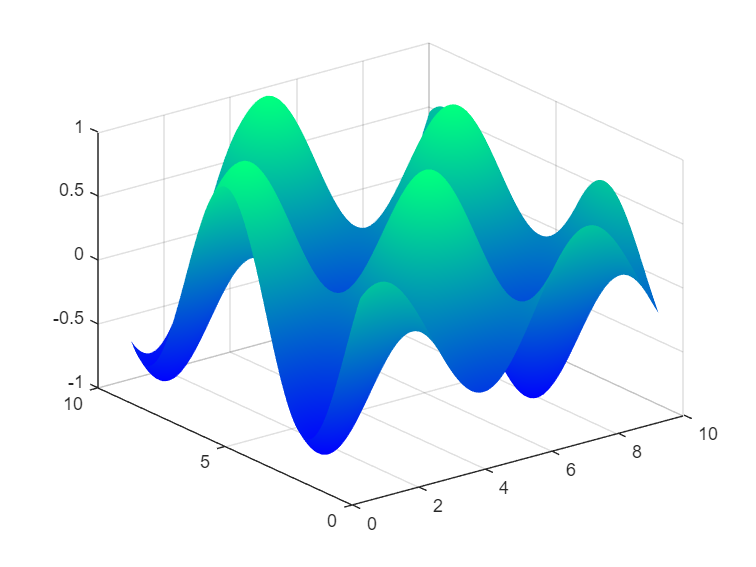

a=linspace(1,10,100);
[x y]=meshgrid(a);
z=sin(x).*cos(y);
surf(x,y,z)
colormap winter % default, spring, summer, autumn, pink
shading interp % flat, faceted

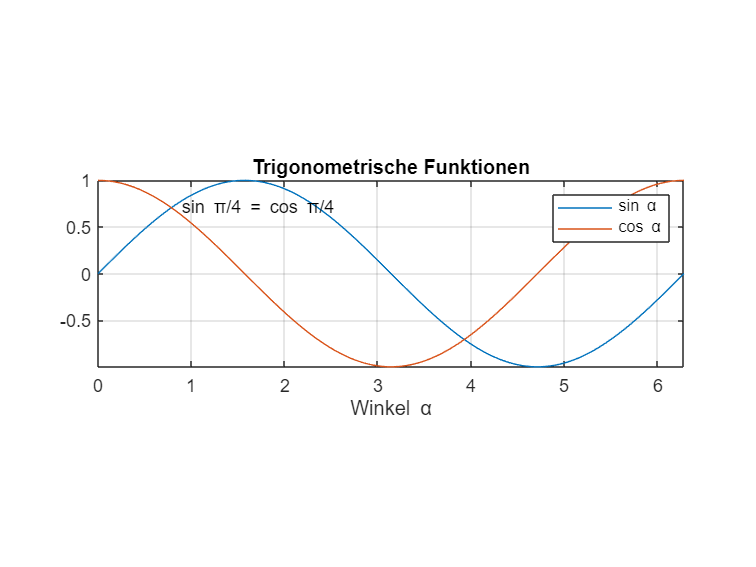

X=linspace(0,2*pi); Y=[sin(X);cos(X)];
plot(X,Y)
title('Trigonometrische Funktionen')
xlabel('Winkel \alpha');
text(pi/4,sin(pi/4),' sin \pi/4 = cos \pi/4')
axis equal
axis tight
grid on
legend(['sin \alpha';'cos \alpha'])

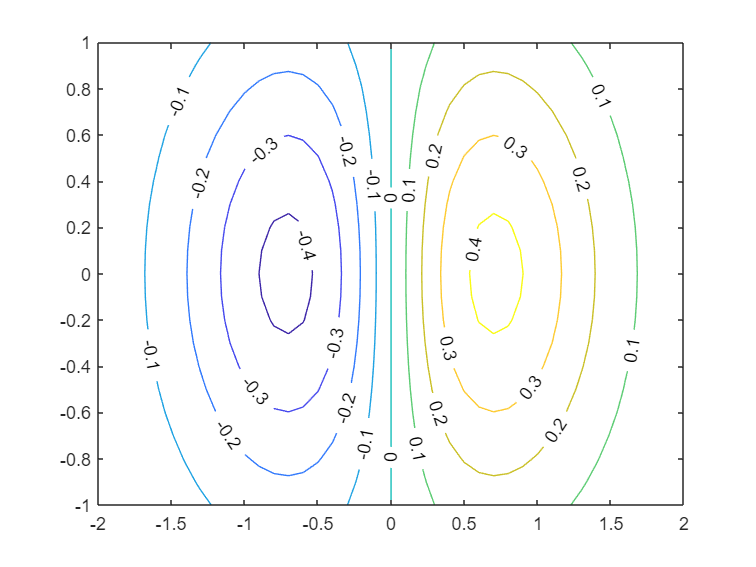

% Контурные графики. Изобразить линии уровня на плоскости xy (функция contour) 
% и подписать для каждой линии уровня соответствующее значение (функция clabel), 
% которое принимает на ней исследуемая функция.

[x,y]=meshgrid(-2:.1:2, -1:.1:1);
z=x.*exp(-x.^2-y.^2);
[c,h]=contour(x,y,z);
clabel(c,h)

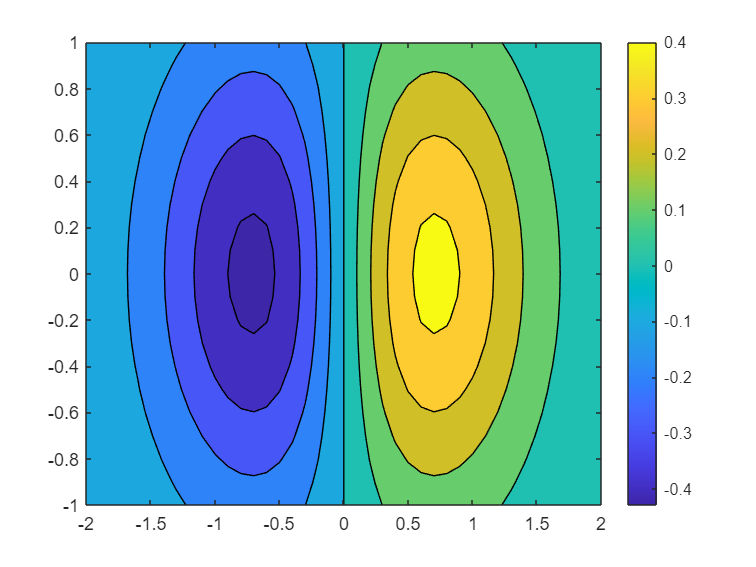

% Наглядную информацию об изменении функции дает заливка 
% прямоугольника на плоскости xy цветом,
% зависящим от значения функции в точках плоскости.
contourf(x,y,z);
colorbar

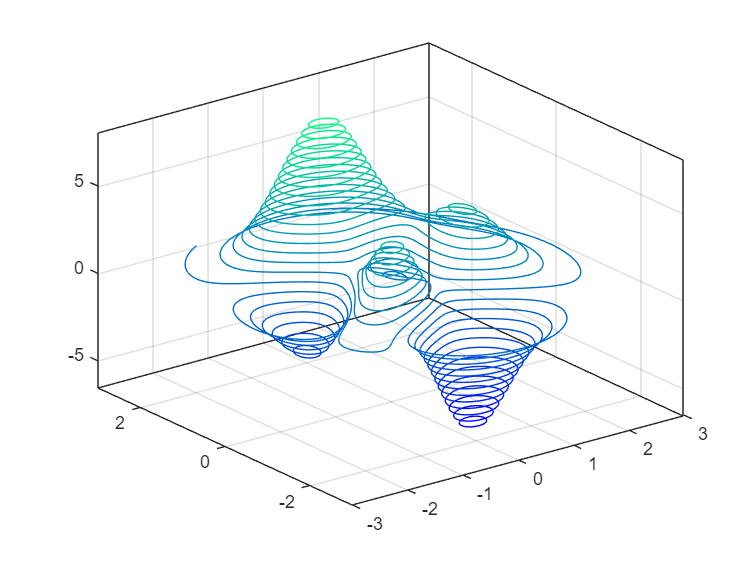

% Построение линий уровня функции двух переменных.
[x,y,z]=peaks(100);
contour3(x,y,z,30);

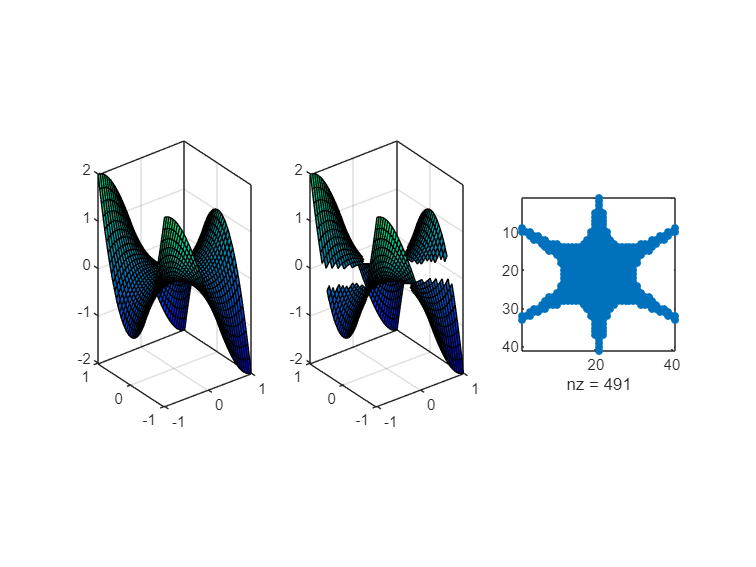

% Построение графиков в разных системах координат в одном графическом окне.
[X,Y]=meshgrid(-1:.05:1);
Z=X.^3-3*X.*Y.^2;
subplot(1,3,1)
surf(X,Y,Z)
axis equal
axis tight
box on

subplot(1,3,2)
ind=abs(Z)<0.1;
Z(ind)=NaN;
subplot(1,3,2)
surf(X,Y,Z)
axis equal
axis tight
box on

subplot(1,3,3)
spy(isnan(Z))
axis equal
axis tight

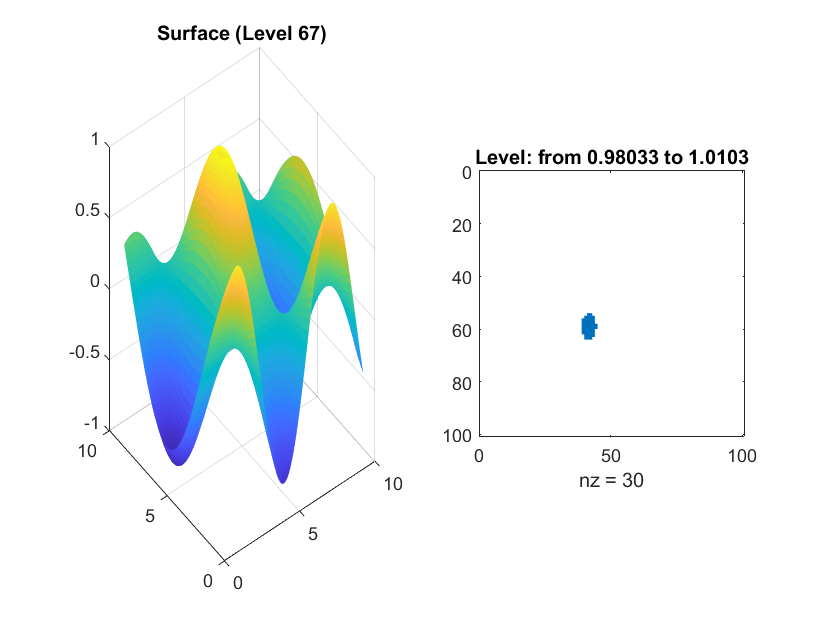

% «Томограмма». 3D-графика и анимация.
% Построить график заданной функции двух переменных 
% и просканировать (снизу вверх) ее горизонтальные уровни

a=linspace(1,10,100);
[x, y]=meshgrid(a);
z=sin(x).*cos(0.5.*y);
j = 1;
step = 0.03;
for i=min(min(z)):step:max(max(z))
    ind = (z >= i) & (z <= (i+step));
    z(ind) = NaN;
    subplot(1,2,1)
    surf(x,y,z)
    title(['Surface (Level ' num2str(j) ')'])
    shading flat
    drawnow
    
    subplot(1,2,2)
    spy(isnan(z))
    title(['Level: from ' num2str(i) ' to ' num2str(i+step)])
    drawnow
    z = sin(x).*cos(0.5.*y);
    j = j + 1;
end